clc
clear
close all

% State-space matrices
A = [0 1; -5 -6];
B = [0; 1];
C = [1 0];
D = 0;

% State-space model
sys = ss(A,B,C,D);

%% Controllability
Co = ctrb(A,B);
rank_Co = rank(Co);

disp('Controllability Matrix:')

Controllability Matrix:


disp(Co)

     0     1
     1    -6




if rank_Co == size(A,1)
    disp('System is Controllable')
else
    disp('System is NOT Controllable')
end

System is Controllable



%% Observability
Ob = obsv(A,C);
rank_Ob = rank(Ob);

disp('Observability Matrix:')

Observability Matrix:


disp(Ob)

     1     0
     0     1




if rank_Ob == size(A,1)
    disp('System is Observable')
else
    disp('System is NOT Observable')
end

System is Observable



%% Transfer function
G = tf(sys)


G =
 
        1
  -------------
  s^2 + 6 s + 5
 
Continuous-time transfer function.


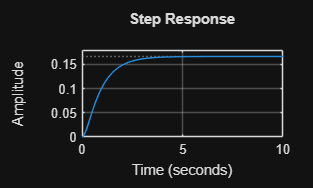


%% Closed loop system
sys_cl = feedback(G,1);

figure
step(sys_cl)
grid on
title('Step Response')


%% Steady state error
dc_gain = dcgain(sys_cl);
ess = 1 - dc_gain;

disp('Steady State Error:')

Steady State Error:


disp(ess)

    0.8333

